# Курс "Дискретные преобразования сигналов"

# Романюк Ю.А., Леус А.В., Тормагов Т.А.

# Лекция 3.

# 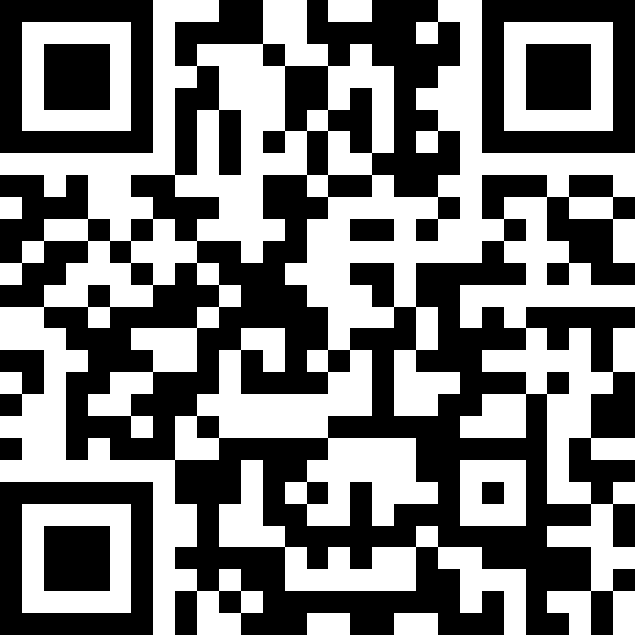

## Дискретизация аналоговых сигналов.

## Спектр дискретизованного сигнала.

## Теорема Котельникова. 

## Эффект наложения спектров. 

## Выбор частоты дискретизации.

### Дискретизация аналоговых сигналов.

Как уже отмечалось в первой главе, *дискретизация *– это переход от континуального сигнала *x*(*t*) к последовательности чисел – коэффициентам разложения сигнала по какому-либо ортогональному базису. С точки зрения организации обработки наиболее удобным способом дискретизации является представление сигналов в виде выборок их значений (отсчётов) в отдельных эквидистантно расположенных точках. Поэтому в качестве базисов дискретизации чаще всего используются сдвиговые базисные функции (функции отсчётов и прямоугольные функции).

В этой главе рассматриваются дискретные представления сигналов, основанные на использовании периодических моментов дискретизации. В таком случае процесс дискретизации эквивалентен амплитудной модуляции последовательности импульсов.

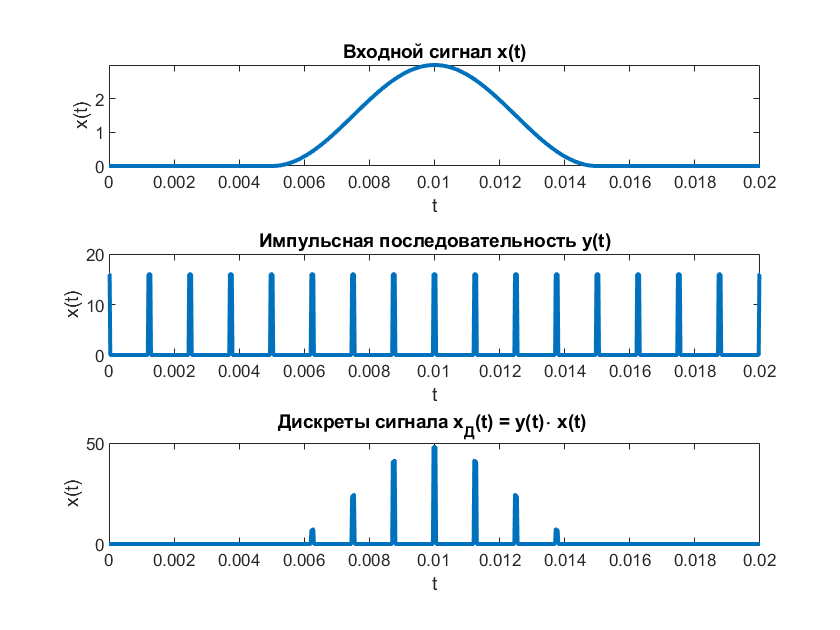

T = 10*10^(-3);
N = 2^10;
t = linspace(0, T, N/2);
F0 = 1/T;
E = 3;
xt = E*(1-cos(2*pi*F0*t))/2; % сигнал
t = linspace(0, 2*T, N);  % наблюдаемый интервал времени
xt = [zeros(1, N/4), xt, zeros(1, N/4)]; % сигнал на наблюдаемом интервале времени
Period = T/(N/64); % период следования прямоугольных импульсов
tau = Period/16; % продолжительность прямоуголных импульсов
% формируем последовательность прямоугольных импульсов
yt = zeros(1,numel(t));
for k=0:T/Period
    yt = yt+Rect(t-2*Period*k,tau, Period);
end
yxt=yt.*xt;
figure;
subplot1 = subplot(3,1,1); plot(t, xt,'LineWidth',2);
set(subplot1,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('t'); ylabel('x(t)'); title('Входной сигнал x(t)');
subplot2 = subplot(3,1,2); plot(t, yt, 'LineWidth',2);
set(subplot2,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('t'); ylabel('x(t)'); title('Импульсная последовательность y(t)');
subplot3 = subplot(3,1,3); plot(t, yxt, 'LineWidth',2);
set(subplot3,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('t'); ylabel('x(t)'); title('Дискреты сигнала x_Д(t) = y(t)\cdot x(t) ');

В пределе дискретизатор можно рассматривать как периодически действующий прерыватель. При этом длительность импульсов $\tau$        практически должна быть исчезающе мала по сравнению с периодом дискретизации $\Delta t$.

Периодическую последовательность прямоугольных импульсов с амплитудой *А*, длительностью $\tau$ и периодом  $\Delta t$ представим в виде ряда Фурье по комплексным экспоненциальным функциям: $\varphi_n \left(t\right)=e^{jn\frac{2\pi t}{\Delta t}}$


$$y\left(t\right)=\sum_{k=-\infty }^{\infty } A\cdot П_{\tau } \left(t-k\Delta t\right)=\sum_{n=-\infty }^{\infty } C_n e^{\mathrm{jn}\frac{2\pi t}{\Delta t}} ,$$


Где $С_n$ - коэффициенты Фурье:


$$С_n =\frac{A}{{\left\|\varphi_n \left(t\right)\right\|}^2 }\int_{-\frac{\tau }{2}}^{\frac{\tau }{2}} П_{\tau } {\left(t\right)e}^{-jn\frac{2\pi t}{\Delta t}} dt=\frac{A\cdot \tau }{\Delta t}\sum_{n=-\infty }^{\infty } {\frac{\mathrm{sin}\left(n\frac{\pi \tau }{\Delta t}\right)}{n\frac{\pi \tau }{\Delta t}}e}^{jn\frac{2\pi t}{\Delta t}}$$


Устремляя $\tau$ к нулю и предполагая, что произведение $A\cdot \tau$ остается постоянным (например, $A\cdot \tau =\Delta t_{\tau \to 0}$), получаем:


$$\underset{\tau \to 0}{\mathrm{lim}} \left(y\left(t\right)\right)=D_{\Delta t} \left(t\right)=\sum_{n=-\infty }^{\infty } e^{\mathrm{jn}\frac{2\pi t}{\Delta t}}$$


Получили ряд Фурье для периодической последовательности $\delta$-функций, следующих с периодом $\Delta t$: $\underset{\tau \to 0}{\mathrm{lim}} \left(y\left(t\right)\right)=D_{\Delta t} \left(t\right)=\Delta t\sum_{n=-\infty }^{\infty } \delta \left(t-k\Delta t\right)\ldotp$

Эту функцию мы будем называть *функцией идеальной дискретизации.* Дискретизованный сигнал можно рассматривать как результат модуляции последовательности $\delta$-функций $D_{\Delta t} \left(t\right)$функцией $x\left(t\right)$:


$$x_Д \left(t\right)=x\left(t\right)\cdot D_{\Delta t} \left(t\right)=\Delta t\sum_{n=-\infty }^{\infty } x\left(k\Delta t\right)\delta \left(t-k\Delta t\right)\ldotp$$


При таком определении функции дискретизации размерности левой и правой части  совпадают.

### Спектр дискретизованного сигнала.

Из предыдущей лекции вспомним, что спектр функции дискретизации $D_{\Delta t} \left(t\right)$ следующий:


$$F\left\lbrace D_{\Delta t} \left(t\right)\right\rbrace \left(f\right)=F\left\lbrace \sum_{n=-\infty }^{\infty } \delta \left(t-k\Delta t\right)\right\rbrace \left(f\right)=\Delta f\sum_{n=-\infty }^{\infty } \delta \left(f-n\Delta f\right),\mathrm{где}\;\Delta f=\frac{1}{\Delta t}\ldotp$$


Здесь и далее $\Delta f=\frac{1}{\Delta t}$ будем называть частотой дискретизации $f_Д =\Delta f=\frac{1}{\Delta t}$.

Тогда:


$$F\left\lbrace D_{\Delta t} \left(t\right)\right\rbrace \left(f\right)=F\left\lbrace \Delta t\sum_{n=-\infty }^{\infty } \delta \left(t-k\Delta t\right)\right\rbrace \left(f\right)=\sum_{n=-\infty }^{\infty } \delta \left(f-{nf}_Д \right)$$


Таким образом, спектр функции дискретизации представляется периодической последовательностью $\delta$-функций, период следования которых на частотной оси равен частоте дискретизации.

Найдем теперь спектр дискретизованного сигнала $x_Д \left(t\right)$. $X\left\lbrace x\left(t\right)\right\rbrace \left(f\right)=X\left(f\right)$ - спектр сигнала $x\left(t\right)\ldotp$

Тогда по теореме о спектре произведения сигналов получим, что спектром будет свертка Фурье-образов исходных сигналов:


$$X_Д \left(f\right)=X\left(f\right)\otimes D_{f_Д } \left(f\right)=\sum_{n=-\infty }^{\infty } \int_{-\infty }^{\infty } \;X\left(f-\tilde{f} \right)\delta \left(\tilde{f} -{nf}_Д \right)d\tilde{f} \ldotp$$
 

С учетом фильтрующего свойства $\delta$-функции получаем:


$$X_Д \left(f\right)=\sum_{n=-\infty }^{\infty } X\left(f-n\cdot f_Д \right)=X\left(f\right)+\sum_{n=1}^{\infty } X\left(f\pm n\cdot f_Д \right)\ldotp$$


Таким образом, дискретизация аналогового сигнала по времени с шагом $\Delta t$ приводит к периодическому повторению его спектра по оси частот с периодом, равным частоте дискретизации $f_Д =\Delta f=\frac{1}{\Delta t}$.

На рис изображён случай, когда спектр аналогового сигнала является финитной функцией и частота дискретизации выбрана так, что частичные спектры не перекрываются.

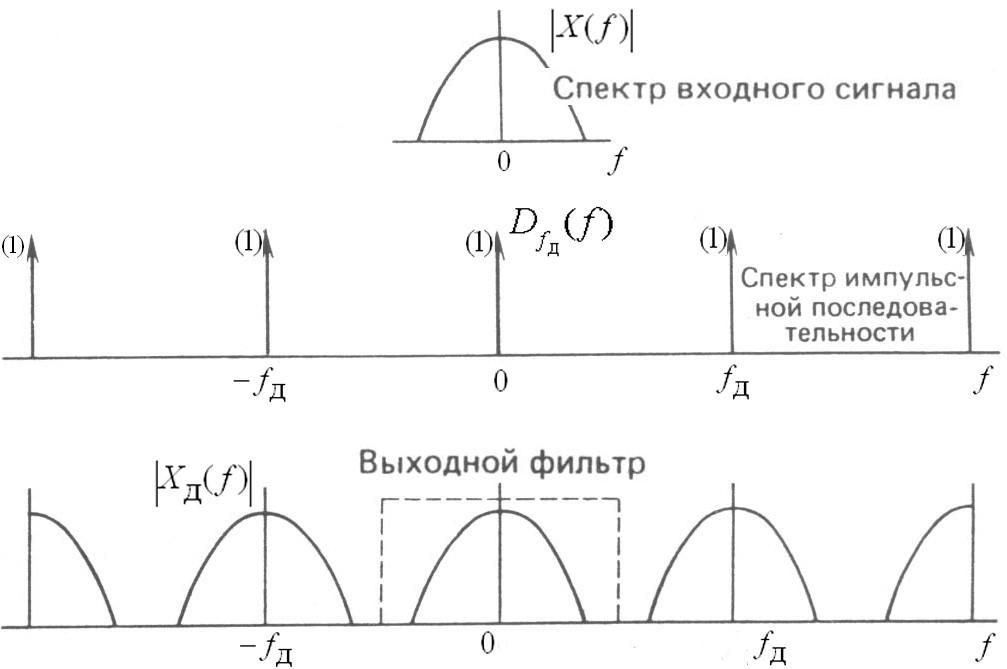                                                    

`Рассмотрим на примере, спектра прямоугольного импульса:`

T = 10*10^(-3);
N = 2^10;
t = linspace(-T, T, N+1);
E = 3;
xt = [zeros(1,(numel(t)-1)/4), E*ones(1,((numel(t))-1)/2+1), zeros(1,(numel(t)-1)/4)];
figure;
subplot1 = subplot(2,1,1); plot(t, xt,'LineWidth',2);
set(subplot1,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('t'); ylabel('x(t)'); title('Прямоугольный импульс');

Вычисляем преобразование Фурье:

 
$$X_T \left(f\right)=\int_{-\frac{T}{2}}^{\frac{T}{2}} E\cdot e^{-j2\pi \mathrm{ft}} \mathrm{dt}=-\frac{E}{2\pi f}\cdot e^{-j2\pi \mathrm{ft}} {\left|\right.}_{-\frac{T}{2}}^{\frac{T}{2}} =-\frac{E}{j2\pi f}\left(e^{-j\frac{2\pi \mathrm{fT}}{2}} -e^{j\frac{2\pi \mathrm{fT}}{2}} \right)=\frac{E}{\pi f}\mathrm{sin}\left(\pi f\;T\right)=E\;T\frac{\mathrm{sin}\left(\pi fT\right)}{\pi fT}\ldotp$$


Строим график:

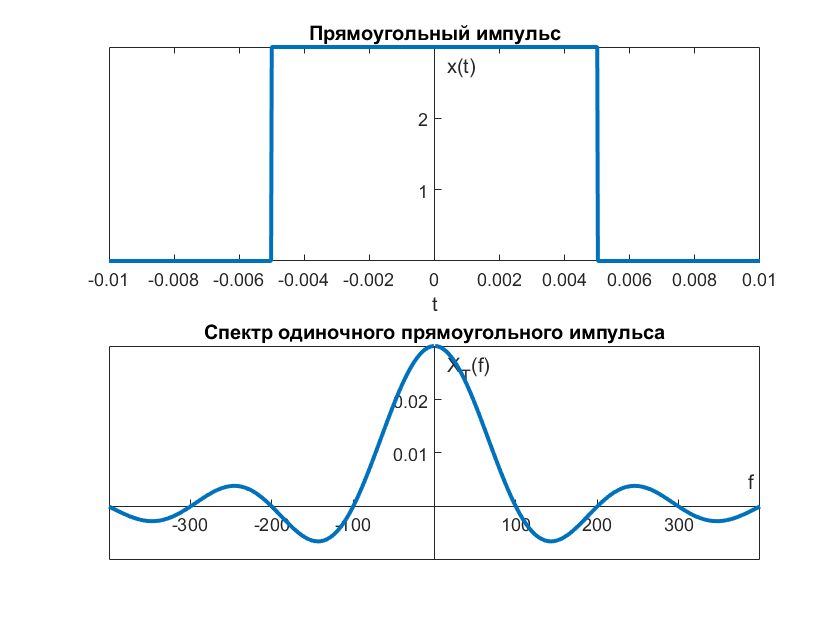

F = 1/T;
f = linspace(-4*F, 4*F, N+1);
XTf = E*sin(pi*T*f)./(pi*f);
subplot2 = subplot(2,1,2); plot(f, XTf, 'LineWidth', 2);
set(subplot2,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('f'); ylabel('X_T(f)'); title('Спектр одиночного прямоугольного импульса');

Дискретизуем сигнал частотой дискретизации $f_Д =\frac{1}{\Delta t}:$

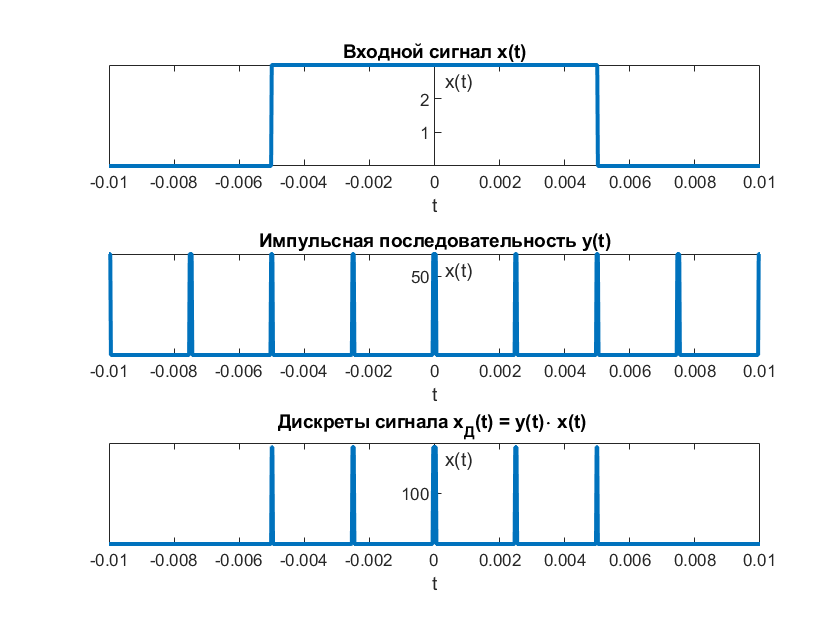

Period = 2*T/(N/128); % период дискретизации
tau = Period/64;
yt = zeros(1,numel(t));

for k=-T/Period:T/Period
    yt = yt+Rect(t+Period*k,tau, Period);
    
end
yxt=yt.*xt;
figure;
subplot1 = subplot(3,1,1); plot(t, xt,'LineWidth',2);
set(subplot1,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('t'); ylabel('x(t)'); title('Входной сигнал x(t)');
subplot2 = subplot(3,1,2); plot(t, yt, 'LineWidth',2);
set(subplot2,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('t'); ylabel('x(t)'); title('Импульсная последовательность y(t)');
subplot3 = subplot(3,1,3); plot(t, yxt, 'LineWidth',2);
set(subplot3,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('t'); ylabel('x(t)'); title('Дискреты сигнала x_Д(t) = y(t)\cdot x(t) ');


FD = 1/Period % Частота дискретизации

FD = 400

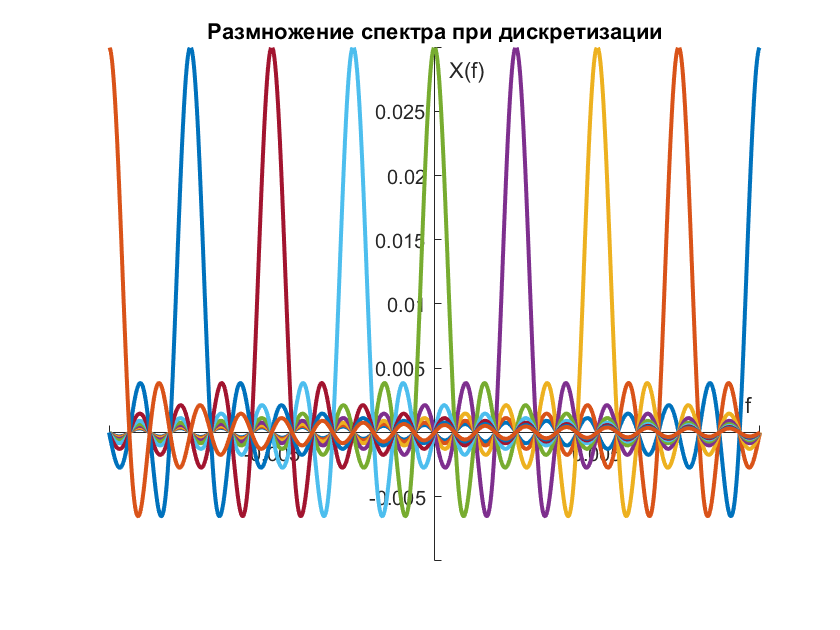

XfD = zeros(1,numel(f));
figure; hold on;
for k=-4:4
    f = linspace(-4*FD+k*FD, (4)*FD+k*FD, N+1);
    XTf = E*sin(pi*T*f)./(pi*f);
    
    subplot1 = subplot(1,1,1); plot(t, XTf, 'LineWidth',2);
    set(subplot1,'XAxisLocation','origin','YAxisLocation','origin');
    xlabel('f'); ylabel('X(f)'); title('Размножение спектра при дискретизации');
    
    XfD = XfD+XTf;
end
hold off;

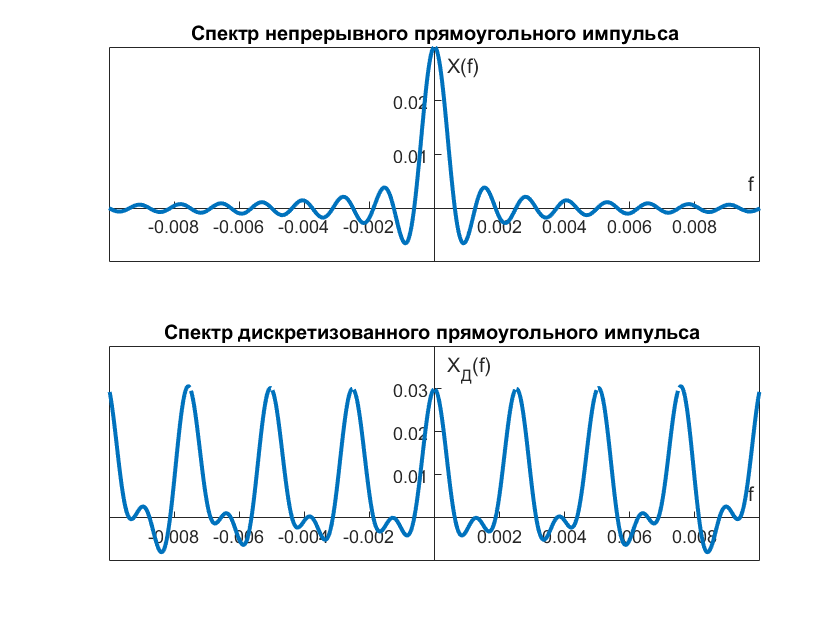

f = linspace(-4*FD, (4)*FD, N+1);
XTf = E*sin(pi*T*f)./(pi*f);
figure
subplot1 = subplot(2,1,1); plot(t, XTf, 'LineWidth',2);
set(subplot1,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('f'); ylabel('X(f)'); title('Спектр непрерывного прямоугольного импульса');
subplot2 = subplot(2,1,2); plot(t, XfD, 'LineWidth',2);
set(subplot2,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('f'); ylabel('X_Д(f)'); title('Спектр дискретизованного прямоугольного импульса ');

### Теорема Котельникова. 

В 1933 году В.А. Котельников доказал теорему, которая имеет фундаментальное значение в физике и технике. В соответствии с этой теоремой аналоговый сигнал  $x\left(t\right)$  при определённых условиях однозначно представляется последовательностью своих отсчётов, взятых через равные промежутки времени. В зарубежной литературе эта теорема называется *теоремой отсчётов*.

Рассмотрим сначала сигналы, которые характеризуются тем, что их ПФ существует на всём интервале частот $\left(-\infty ,\infty \right)$ но отлично от нуля только на конечном интервале $\left\lbrack -f_в ,f_в \right\rbrack \ldotp$

*Если сигнал имеет спектр, ограниченный интервалом* $\left\lbrack -f_в ,f_в \right\rbrack$ *и шаг дискретизации* $\Delta t=\frac{1}{2f_в }$,  *то коэффициенты* *Фурье*   *разложения сигнала по функциям отсчётов* $\varphi_k \left(t\right)$ *являются выборками сигнала* $x\left(k\Delta t\right)$*и для* $x\left(t\right)$*имеет место представление рядом Котельникова*:


$$x\left(t\right)=\sum_{k=-\infty }^{\infty } x\left(k\Delta t\right)\frac{\mathrm{sin}\left(2\pi f_в \left(t-k\Delta t\right)\right)}{2\pi f_в \left(t-k\Delta t\right)}\ldotp$$


Таким образом, приведённые выше соотношения иллюстрируют возможность точного восстановления континуального сигнала $x\left(t\right)$ по его дискретным отсчётам $x\left(k\Delta t\right)$. 

*Замечание*. Важно отметить, что любой ряд Котельникова представляет функцию с финитным спектром.

Теорема Котельникова относится к числу фундаментальных результатов и широко используется в теории и практике обработки сигналов. Так, например, чтобы передать по каналу связи непрерывное сообщение $x\left(t\right)$ с финитным спектром, можно поступить следующим образом:

- взять отсчеты $x\left(k\Delta t\right)$; 

- передать величины этих отсчетов;

- на приемном конце сформировать короткие импульсы с площадями $\Delta t\cdot x\left(k\Delta t\right)$; 

- восстановить сообщение с помощью фильтра нижних частот с полосой $\left\lbrack -f_в ,f_в \right\rbrack$ и постоянным в пределах этой полосы коэффициентом передачи, подавая на вход фильтра сформированные короткие импульсы. 

### Эффект наложения спектров. 

Сигналы с нефинитным спектром

Реально, любой сигнал наблюдается в течение конечного интервала времени  T. Спектр такого сигнала строго не является финитной функцией, т. е. будет неограничен по протяженности. В этом случае выбор верхней граничной частоты $f_в$  является условным. Дискретизованный с некоторым шагом $\Delta t=\frac{1}{2f_в }$ сигнал будет иметь спектр $X_Д \left(f\right)$, как продемонстрировано в примере.  Таким образом, при дискретизации сигнала с неограниченным спектром периодическое повторение спектра, вызванное дискретизацией, будет сопровождаться *эффектом наложения* (“aliasing”) частичных спектров своими "хвостами". В силу неограниченной протяженности исходного спектра этот эффект принципиально неустраним при любом $\Delta t$  (он может быть только ослаблен выбором малого  $\Delta t$). 

Можно перечислить основные причины, по которым восстановленный  сигнал будет отличаться от исходного:

- спектры реальных сигналов ограничены по частоте приближенно; 

- невозможно измерить отсчёты сигнала за бесконечно малый промежуток времени;

- отличие реальных фильтров восстановления от идеального фильтра нижних частот;

- отличие импульсов отсчетов от $\delta$-функции;

- конечное число отсчетов.

### Выбор частоты дискретизации.

В реальных системах частоту дискретизации выбирают из условия $f_Д >2f_в$. Обычно $f_Д =\left(2,3\ldotp \ldotp \ldotp 2,4\right)\;f_в$. Так, при дискретизации телефонных сигналов с диапазоном частот 0,3...3,4 кГц частота дискретизации равна 8 кГц (рисунок 1.9).

FD = 1/Period % Частота дискретизации

FD = 400

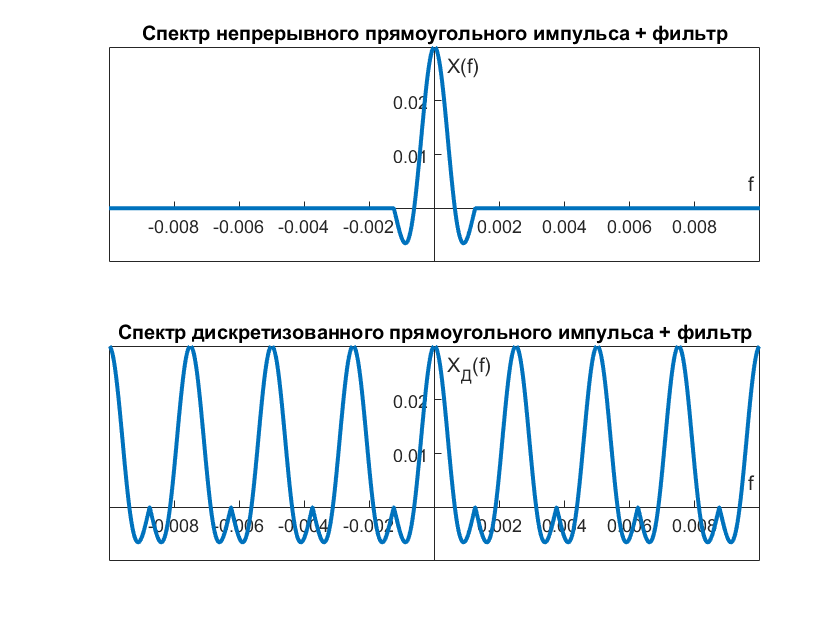

XfD = zeros(1,numel(f));
for k=-4:4
    f = linspace(-4*FD+k*FD, (4)*FD+k*FD, N+1);
    XTf = E*sin(pi*T*f)./(pi*f);
    f1 = Filt(f, FD);
    XTf = XTf.*f1;
    % figure; plot (XTf);
    XfD = XfD+XTf;
end
f = linspace(-4*FD, (4)*FD, N+1);
XTf = E*sin(pi*T*f)./(pi*f);
f1 = Filt(f, FD);
XTf = XTf.*f1;
figure
subplot1 = subplot(2,1,1); plot(t, XTf, 'LineWidth',2);
set(subplot1,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('f'); ylabel('X(f)'); title('Спектр непрерывного прямоугольного импульса + фильтр');
subplot2 = subplot(2,1,2); plot(t, XfD, 'LineWidth',2);
set(subplot2,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('f'); ylabel('X_Д(f)'); title('Спектр дискретизованного прямоугольного импульса + фильтр');

function Rect = Rect(t, tau, Period)
Rect = zeros(1,length(t));
for n=1:length(t)
    if abs(t(n)) <= tau
        Rect(n) = Period/tau;
    end
end
end

function Filt = Filt (f, deltaf)
Filt = zeros(1,length(f));
for n=1:length(f)
    if abs(f(n)) <= deltaf/2
        Filt(n) = 1;
    end
end
end
